# Sprawozdanie z przedmiotu Przetwarzanie sygnałów cyfrowych

Laboratoria 12

## Zad 1

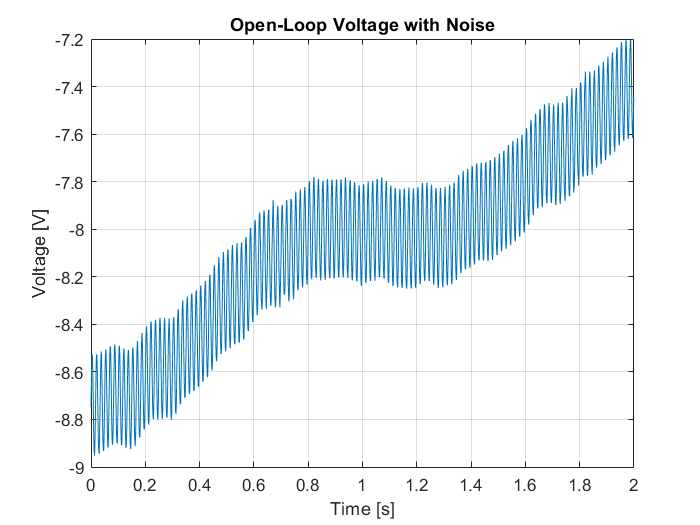

clear all
figure
load openloop60hertz, openLoop=openLoopVoltage;
Fs=1000;
t=(0:length(openLoop)-1)/Fs;
plot(t, openLoop); box on; grid on;
ylabel 'Voltage [V]', xlabel 'Time [s]'
title 'Open-Loop Voltage with Noise' 

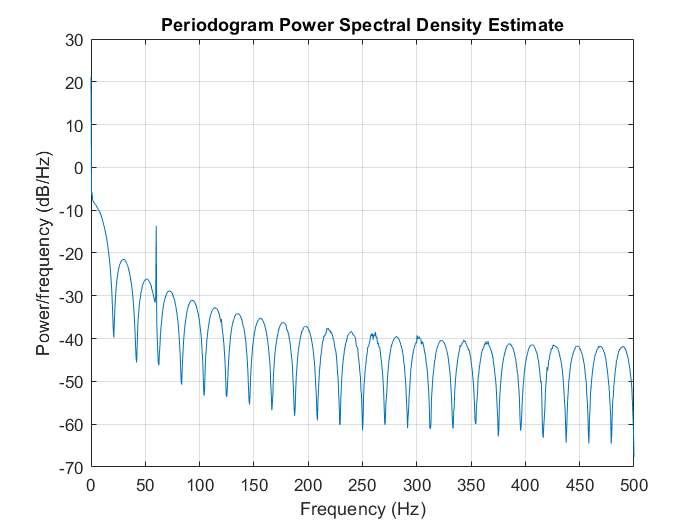


figure;
periodogram(openLoop, [], [], Fs); 

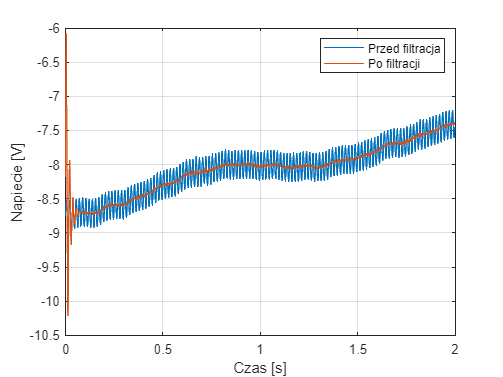


filtCoeff= designfilt('bandstopiir', 'FilterOrder', 2,...
'HalfPowerFrequency1', 49, 'HalfPowerFrequency2', 71, ...
'SampleRate', Fs);

fvtool(filtCoeff)
noiseFreeSignal= filter(filtCoeff, openLoop);


close all;
figure;
plot (t, openLoop, t, noiseFreeSignal); grid on;
legend('Przed filtracja', 'Po filtracji');
ylabel 'Napiecie [V]', xlabel 'Czas [s]'

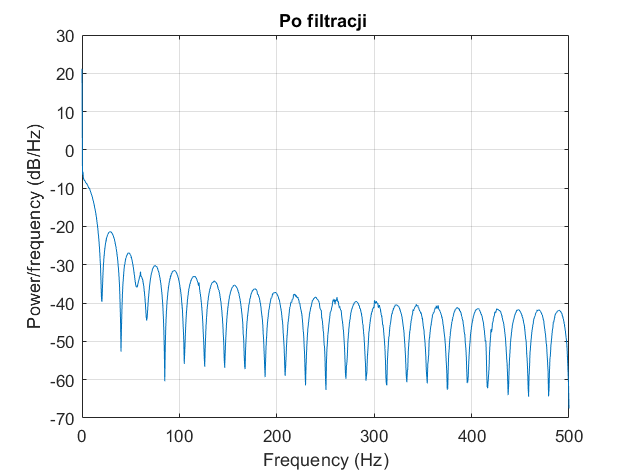



figure;
periodogram(noiseFreeSignal, [], [], Fs);
title('Po filtracji ');

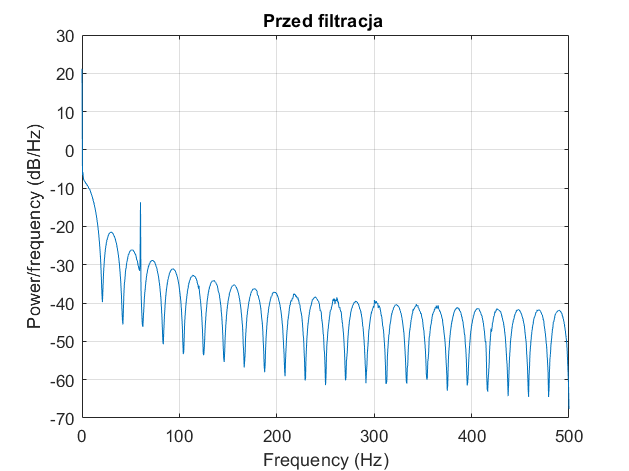

figure;
periodogram(openLoop, [], [], Fs);
title('Przed filtracja '); 

## Zad 2

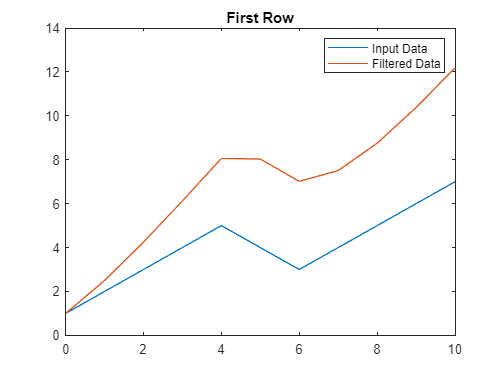

rng default %losowe liczby
x = [1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];
b = 1; 
a = [1 -0.5];
y = filter(b,a,x,[],2);
t = 0:length(x)-1; %indeks wektora
plot(t,x(1,:))
hold on
plot(t,y(1,:))
legend('Input Data','Filtered Data')
title('First Row') 
hold off

## Zad 3

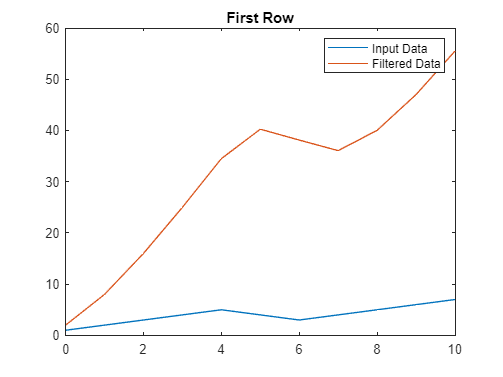

rng default %losowe liczby
x = [1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];
b = [2 3]; 
a = [1 -0.5];
y = filter(b,a,x,[],2);
t = 0:length(x)-1; %indeks wektora
plot(t,x(1,:))
hold on
plot(t,y(1,:))
legend('Input Data','Filtered Data')
title('First Row') 

## Zad 4

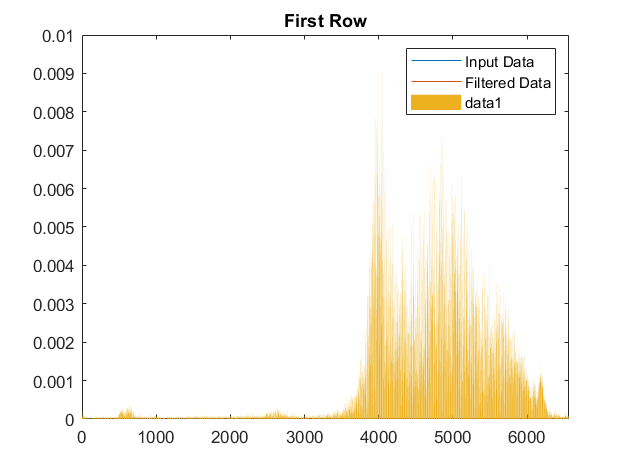

load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

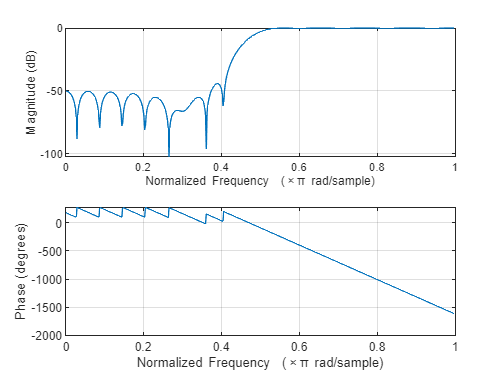

bhi = fir1(34,0.48,'high',chebwin(35,30));
freqz(bhi,1)

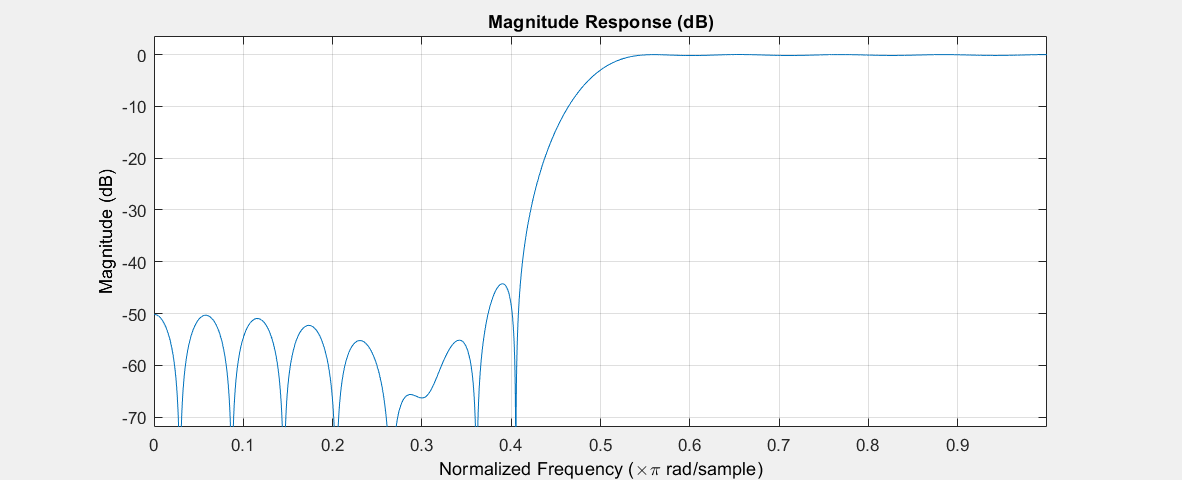

fvtool(bhi)

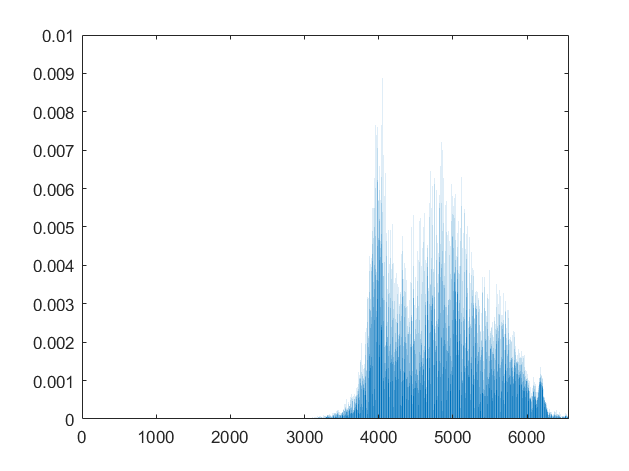

outhi = filter(bhi,1,y);
xfft=abs(fft(outhi));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

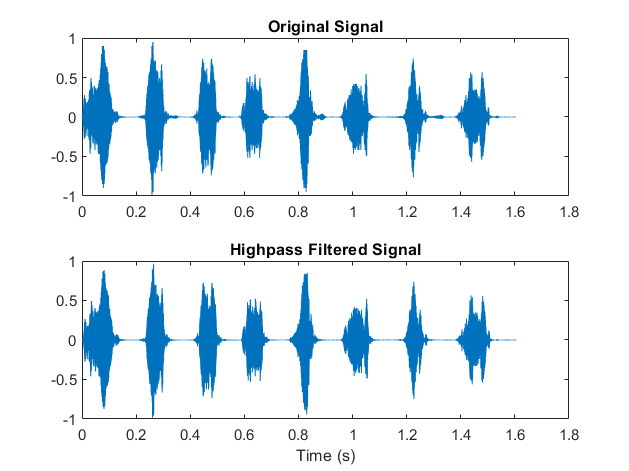

figure
hold on
subplot(2,1,1)
plot(t,y)
title('Original Signal')
ys = ylim;
subplot(2,1,2)
plot(t,outhi)
title('Highpass Filtered Signal')
xlabel('Time (s)')
ylim(ys)
hold off

## Zad 5

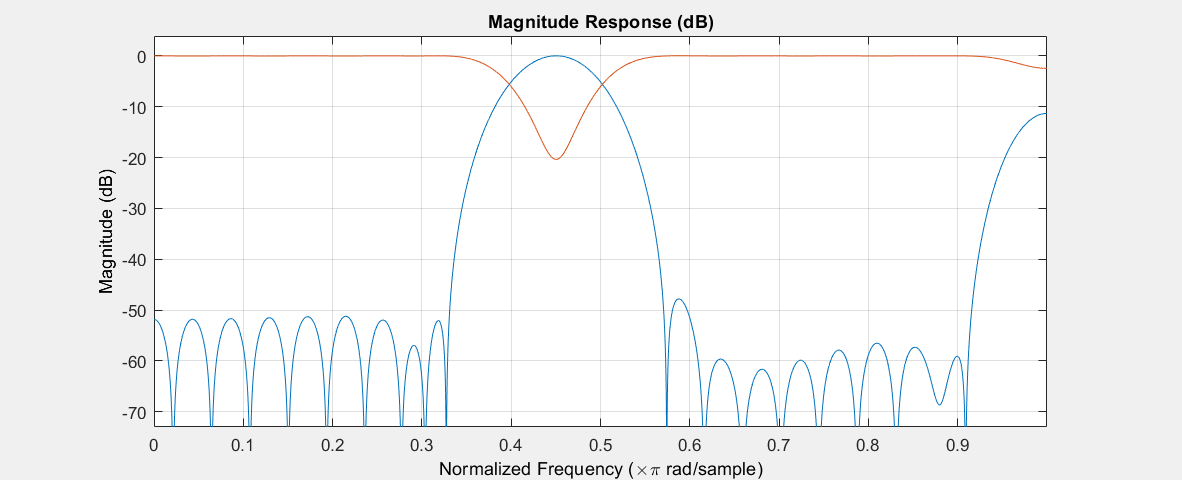

load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
ord = 46;
low = 0.4;
bnd = [0.5 0.99];
bM = fir1(ord,[low bnd]);
bW = fir1(ord,[low bnd],'DC-1');
fvtool(bM, 1, bW, 1)

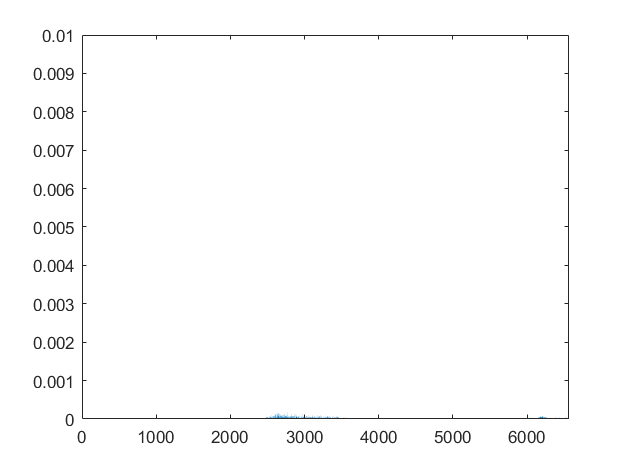

outF = filter(bM,1,y);
xfft=abs(fft(outF));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

## Zad 6

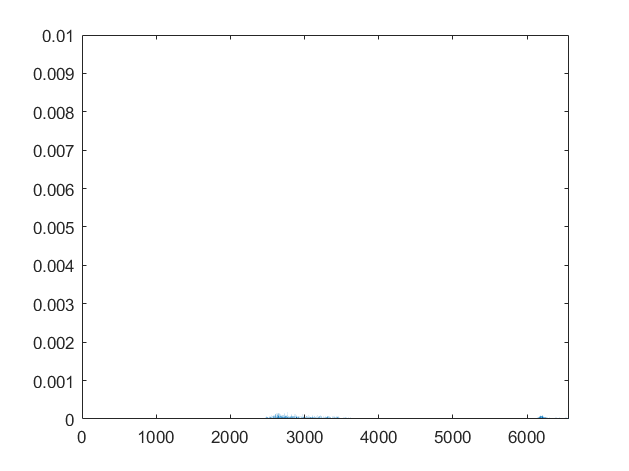

load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
hM = fir1(ord,[low bnd],'DC-0',hann(ord+1));
hfvt = fvtool(bM,1,hM,1); %porownanie okien
legend(hfvt,'Hamming','Hann')
outhann = filter(hM,1,y);
xfft=abs(fft(outhann));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

## Zad 7

x2=data;

Unrecognized function or variable 'data'.

% normalizacja do przedzialu [-1, 1] jesli sygnaly sa mierzone w roznych odleglosciach
max_data=max(abs(data));
data=data/max_data;
xfft=abs(fft(x2));
xfft=xfft/44100;
xfft(500:1000)=0;
load FFT_filtracja_wiatrak20b.txt
load FFT_filtracja_wiatrak21b.txt
load FFT_filtracja_przekladnia20b.txt
load FFT_filtracja_przekladnia21b.txt
load FFT_filtracja_wiatrak23b.txt
load FFT_filtracja_wiatrak24b.txt
load FFT_filtracja_przekladnia23b.txt
load FFT_filtracja_przekladnia24b.txt


D=sum(abs(FFT_filtracja_wiatrak23b-FFT_filtracja_wiatrak20b))
D=sum(abs(FFT_filtracja_wiatrak23b-FFT_filtracja_wiatrak21b))
D=sum(abs(FFT_filtracja_wiatrak23b-FFT_filtracja_przekladnia20b))
D=sum(abs(FFT_filtracja_wiatrak23b-FFT_filtracja_przekladnia21b))


D=sum(abs(FFT_filtracja_wiatrak24b-FFT_filtracja_wiatrak20b))
D=sum(abs(FFT_filtracja_wiatrak24b-FFT_filtracja_wiatrak21b))
D=sum(abs(FFT_filtracja_wiatrak24b-FFT_filtracja_przekladnia20b))
D=sum(abs(FFT_filtracja_wiatrak24b-FFT_filtracja_przekladnia21b))


D=sum(abs(FFT_filtracja_przekladnia23b-FFT_filtracja_wiatrak20b))
D=sum(abs(FFT_filtracja_przekladnia23b-FFT_filtracja_wiatrak21b))
D=sum(abs(FFT_filtracja_przekladnia23b-FFT_filtracja_przekladnia20b))
D=sum(abs(FFT_filtracja_przekladnia23b-FFT_filtracja_przekladnia21b))


D=sum(abs(FFT_filtracja_przekladnia24b-FFT_filtracja_wiatrak20b))
D=sum(abs(FFT_filtracja_przekladnia24b-FFT_filtracja_wiatrak21b))
D=sum(abs(FFT_filtracja_przekladnia24b-FFT_filtracja_przekladnia20b))
D=sum(abs(FFT_filtracja_przekladnia24b-FFT_filtracja_przekladnia21b))


D=sum(abs(FFT_filtracja_wiatrak23b-FFT_filtracja_wiatrak20b))
D=sum(abs(FFT_filtracja_wiatrak23b-FFT_filtracja_wiatrak21b))
D=sum(abs(FFT_filtracja_wiatrak23b-FFT_filtracja_przekladnia20b))
D=sum(abs(FFT_filtracja_wiatrak23b-FFT_filtracja_przekladnia21b))
